# DCモータの過渡特性の取得

## 実験パラメータの設定

clear all;

SAMPLING_TIME = 0.025;  % 1サンプルの頻度は25[ms]程度であることを予備実験で確認
INPUT_VOLTAGE = -0.5;
STEP_TIME = 5;
END_TIME = 10;

## データのサンプル

### デバイスへの接続

serialList = serialportlist;
if size(serialList) == 1
    s = serialport(serialList(1), 57600, "byteOrder", "big-endian", "Timeout", 0.1);
else
    disp('Error: 複数のシリアルデバイスが接続されています');
end

### データのサンプリング

for i = 1 : (END_TIME / SAMPLING_TIME)
    tic;
    if (i >= STEP_TIME / SAMPLING_TIME)
        input_voltage(s, INPUT_VOLTAGE);
    else
        input_voltage(s, 0);
    end
    sh2pc(i) = sci_read_with_decode_using_checksum(s);
    
pause(SAMPLING_TIME - toc);
end

### デバイスの切断

デバイスを切断する

input_voltage(s, 0);
pause(0.5);
clear s;

## 実験結果のプロット

sh2pcTable = struct2table(sh2pc);

### 制御周期のプロット

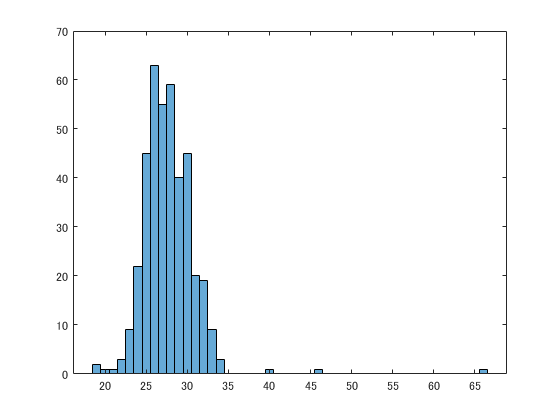

histogram(sh2pcTable.TMStamp(2:end) - sh2pcTable.TMStamp(1:end-1));

### 角度のプロット

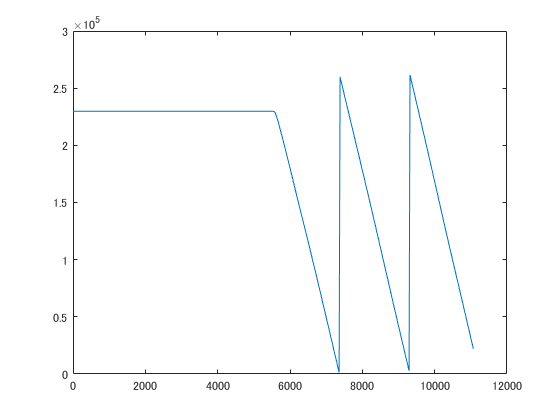

t = sh2pcTable.TMStamp - sh2pcTable.TMStamp(1);
y = sh2pcTable.BaseAngle;
plot(t, y);

### 角速度のプロット

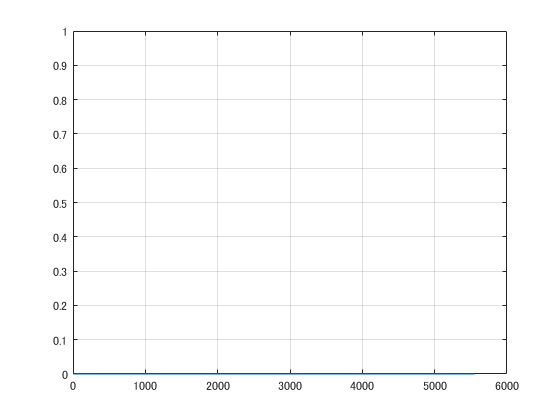

figure;
denc = sh2pcTable.BaseAngle(2:end) - sh2pcTable.BaseAngle(1:end-1);
denc(abs(denc) > 0x0001FFFF) = denc(abs(denc) > 0x0001FFFF) - sign(denc(abs(denc) > 0x0001FFFF)) * int64(0x0003FFFF);
omg = double(denc) * 2 * pi / 2000000 ./ double(t(2:end) - t(1:end-1)) * 1000;
plot(t, [0; omg]);
ylim([0 1])
grid on